clear all;
addpath('C:\Users\migue\OneDrive - uantwerpen\Documents\MATLAB\Examples\R2019b\wlan\MACFrameGenerationExample')

%loading packet
qos_data = load('qos_data.mat');

sampleRate = 20e6;
oversampling = 1.0;

masterClockRate = sampleRate*oversampling;
platform = 'B200';
serialNum = '310A880';
centerFrequency = 2.412e9;
numFramesInBurst = 1

numFramesInBurst = 1

cm = 1; %selected TX
sdrTransmitter = comm.SDRuTransmitter('Platform', platform, 'SerialNum', serialNum, ...
  'CenterFrequency', centerFrequency, ...
  'MasterClockRate', masterClockRate, ...
  'InterpolationFactor', 1, ...
  'Gain', 20, ...
  'ChannelMapping', cm, ...
  'EnableBurstMode', true, ...
  'NumFramesInBurst', numFramesInBurst);
sdrTransmitter

sdrTransmitter =   comm.SDRuTransmitter with properties:

                 Platform: 'B200'
                SerialNum: '310A880'
           ChannelMapping: 1
          CenterFrequency: 2.4120e+09
    LocalOscillatorOffset: 0
                     Gain: 20
                PPSSource: 'Internal'
              ClockSource: 'Internal'
          MasterClockRate: 20000000
      InterpolationFactor: 1
        TransportDataType: 'int16'
          EnableBurstMode: true
         NumFramesInBurst: 1


%configuring sdr -> Not clear why the oversampling but follows example from
%https://nl.mathworks.com/help/wlan/examples/image-transmission-and-reception-using-wlan-toolbox-and-one-plutosdr.html
%which works well. 

psdu_d = reshape(de2bi(hex2dec(qos_data.p1), 8)', [], 1);
%psdu_d = double(psdu_t)

% create pcap to visualize the wlan qos data frame
helperWLANExportToPCAP({qos_data.p1}, 'macFrames_p1.pcap');


%create HT object
HTconfig = wlanHTConfig;
HTconfig.GuardInterval="Short";
HTconfig.MCS=7;
HTconfig.PSDULength = length(qos_data.p1);   % Set the PSDU length
HTconfig.AggregatedMPDU=0;

% Initialize the scrambler with a random integer for each packet
%scramblerInitialization = randi([1 127],1,1);

% Generate baseband HT packets separated by idle time
txWaveform_t = wlanWaveformGenerator(psdu_d,HTconfig);

% Resample transmit waveform
txWaveform_t  = resample(txWaveform_t,sampleRate*oversampling,sampleRate);

fprintf('\nGenerating WLAN transmit waveform:\n')


Generating WLAN transmit waveform:


% Scale the normalized signal to avoid saturation of RF stages
powerScaleFactor = 0.8;
txWaveform_t = txWaveform_t.*(1/max(abs(txWaveform_t))*powerScaleFactor);
% Cast the transmit signal to int16, this is the native format for the SDR
% hardware
txWaveform_t_int = int16(txWaveform_t*2^15);

for i=1:20
    underrun = sdrTransmitter(txWaveform_t_int);
    if underrun~=0
         disp(['Underrun detected in packet # ', int2str(i)]);
    end
    %sdrTransmitter(txWaveform_t_int)
end

Underrun detected in packet # 18


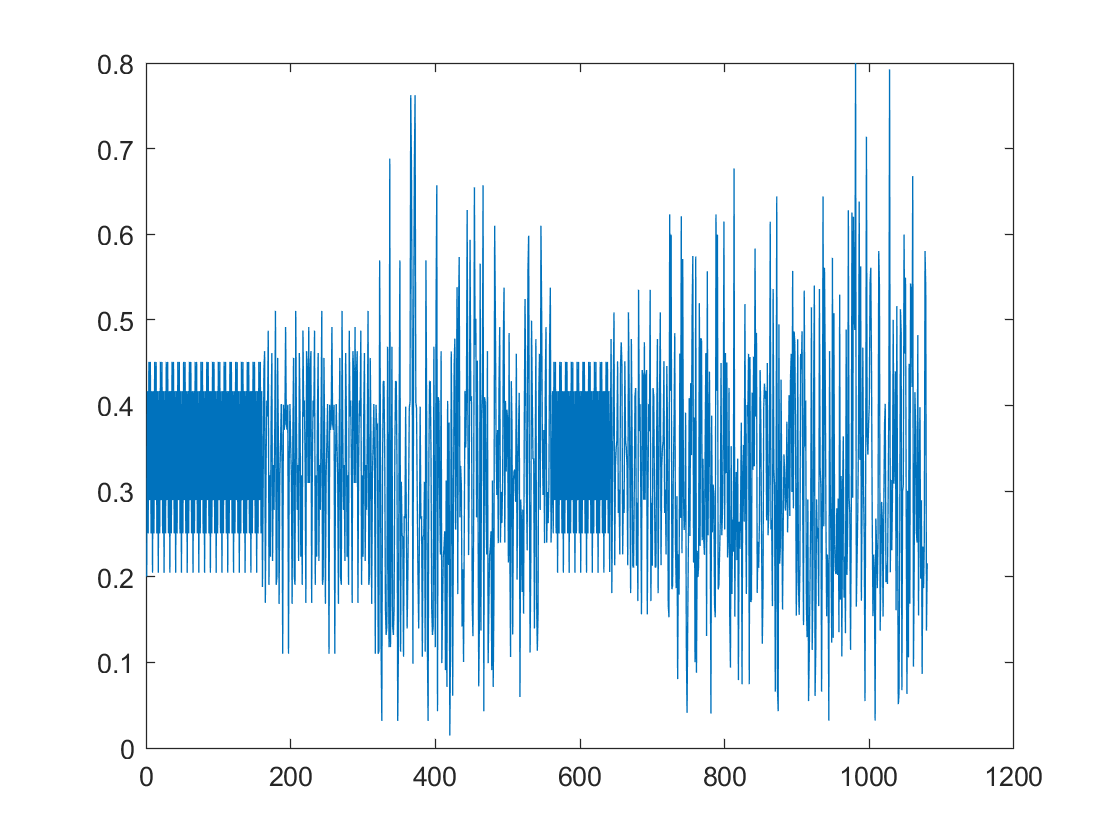


sdrTransmitter.release()
plot(abs(txWaveform_t))

[rxFrameCfg, rxMSDU, status] = wlanMPDUDecode(qos_data.p1, HTconfig,'DataFormat', 'octets');